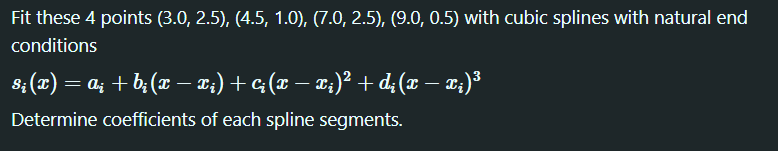

Data 

x = [3.0 4.5 7.0 9.0];
y = [2.5 1.0 2.5 0.5];

plot(x,y,'ko')
hold on

Cubic spline (using spline)

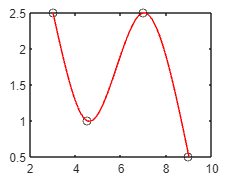

% Given data points
x = [3.0, 4.5, 7.0, 9.0];
y = [2.5, 1.0, 2.5, 0.5];

% Define the points at which you want to interpolate
xx = 3 : 0.1 : 9;

% Generate the interpolated values using cubic spline with natural end conditions
pp = csape(x, y, 'variational', 'second'); % 'variational' option enforces natural end conditions
yy = ppval(pp, xx); % Evaluate the spline at specified points

% Plot the original data points
plot(x, y, 'ko')
hold on

% Plot the interpolated spline
plot(xx, yy, 'r-')
hold off


x_test = 5;
y_pred = ppval(pp,x_test)

y_pred = 1.1029